## 行列式的值

使用 det(A) 求矩阵 A 的值

A = [1,2,1;1,2,4;1,1,1]

A =      1     2     1
     1     2     4
     1     1     1


det(A)

ans = 3

## 秩

使用 rank(A) 求矩阵 A 的秩

A = [1,2,1;1,2,4;1,1,1];
rank(A)

ans = 3

验证 3-20 魔方阵的秩

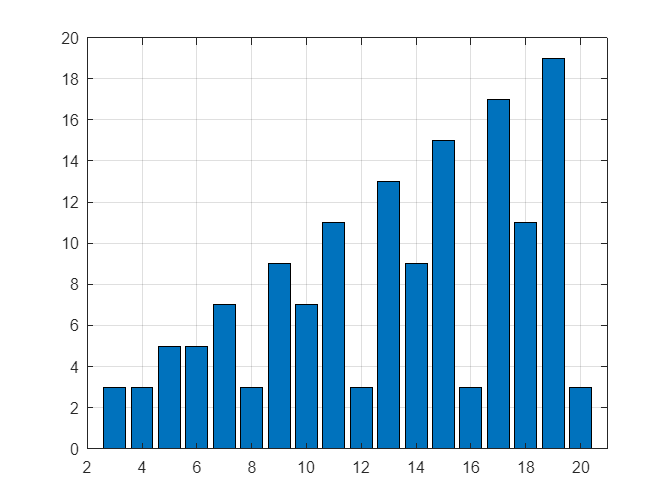

for n=3:20
    r(n)=rank(magic(n));
end
bar(r)
grid on
axis([2,21,0,20])

## 迹

使用 trace(A) 求矩阵 A 的迹

A = [1,2,1;1,2,4;1,1,1];
trace(A)

ans = 4

## 范数

向量三范数：

- 1——范数：向量元素绝对值之和；

- 2——范数：向量元素绝对值平方和的绝对值；

- inf——范数：所有向量元素绝对值的最大值。

使用 norm(A，1) 求向量 A 的 1——范数

A = [1,2,3];
norm(A,1)

ans = 6

使用 norm(A,2) 或 norm(A) 求向量 A 的 2——范数

norm(A)

ans = 3.7417

使用 norm(A,inf) 求向量 A 的 inf——范数

norm(A,inf)

ans = 3

矩阵三范数：

- 1——范数：所有矩阵列元素绝对值之和的最大值；

- 2——范数：A'A 的最大特征值的平方根；

- inf——范数：所有矩阵行元素绝对值之和的最大值。

使用 norm(B,1) 求矩阵 B 的 1——范数

B = [1,2,3;4,5,6];
norm(B,1)

ans = 9

使用 norm(B,2) 或 norm(B) 求矩阵 B 的 2——范数

norm(B)

ans = 9.5080

使用 norm(B,inf) 求矩阵 B 的 inf——范数

norm(B,inf)

ans = 15

## 条件数

矩阵的条件数为矩阵范数与逆矩阵范数的乘积，越接近 1，性能越好。

使用 cond(A,1) 求矩阵 A（方阵）的 1——范数下的条件数

A = [1,2,3;4,5,6;7,8,9];
cond(A,1)

ans = 6.4852e+17

使用 cond(A,2) 或 cond(A) 求矩阵 A 的 2——范数下的条件数

cond(A)

ans = 3.8131e+16

使用 cond(A,inf) 求矩阵 A（方阵） 的 inf——范数下的条件数

cond(A,inf)

ans = 8.6469e+17

## 特征值与特征向量

使用 D = eig(A) 求矩阵 A 的全部特征值给 D。

A = [1,2,3;4,5,6;7,8,9];
D = eig(A)

D =    16.1168
   -1.1168
   -0.0000


使用 [X D] = eig(A) 求矩阵 A 的全部特征值给 D，对应特征向量给 X

[X D] = eig(A)

X =    -0.2320   -0.7858    0.4082
   -0.5253   -0.0868   -0.8165
   -0.8187    0.6123    0.4082


D =    16.1168         0         0
         0   -1.1168         0
         0         0   -0.0000
